# RSC, Breadth-first search

The following code uses the PRM method to generate random points in the free part of the map, and then join the points to generate the graph.

Then the path from the starting point to the end point is obtained using the BFS algorithm. 

Finally the path is made smoother.

clear; clc; close all;

Definition of global parameters

global length_step radius_curve num_iterations points counter occupancy_matrix map samplePoints connections curve_points
% Load map from a .mat file
% data = load('map_straight_with_roundabout.mat');
data = load('test/Files_mat/maps_5_1.mat');

% Check available fields in 'data' structure
disp(fieldnames(data));

    {'invertedImage'}




% Extract map from data structure
% map = data.map_straight_with_roundabout';
map = data.invertedImage';

length_step = 8;            % Length of the step forward
radius_curve = 6;            % Bending radius for left and right curves
num_iterations = 500;        % Number of iterations
curve_points = struct('start_node', [], 'end_node', [], 'points', {});
samplePoints = [];
connections = [];

Start and goal point coordinates for the maps

% %% maps_5_1
Qs = [30, 80];
Qg = [298, 188];            %228/162, 202/32  10/8      288/118, 298/188 8/6

%% map_straight_with_roundabout
% Qs = [50, 40];
% Qg = [415, 30];              %15/10
% Qg = [415, 35];            %20/15

Variable initialization

% Vector for points
points = zeros(((num_iterations + 1)^3), 2);
points(1, :) = Qs;

% Occupancy matrix
occupancy_matrix = zeros(size(map));
occupancy_matrix(Qs(1), Qs(2)) = 1;         % Mark start point as visited
occupancy_matrix(map == 0) = 1;             % Mark cells with obstacles as visited

% Point counter
counter = 1;

% Queue for points to explore
queue = [Qs, 0, 1];         % [x, y, angle, iteration]

Plot initialization

figure;
imshow(map');
hold on;
% Plotting the start and goal points on the map
plot(Qs(1), Qs(2), 'ro', 'MarkerSize', 10, 'LineWidth', 1.5);                      % Start point (red)
plot(Qg(1), Qg(2), 'go', 'MarkerSize', 10, 'LineWidth', 1.5);                      % Goal point (blue)

Initiation of proceedings from start point

while ~isempty(queue)
    % Extract the current point from the queue
    current_point = queue(1, 1:2);
    current_angle = queue(1, 3);
    iteration = queue(1, 4);
    queue(1, :) = [];                   % Remove the item from the queue

    % Calculate new points and add them to the queue if not visited
    new_points = calculate_points(current_point, current_angle, iteration);
    queue = [queue; new_points];                % Add new points to the queue
end

Adding the final notes on the plot figure

title('Primitive Reed-Sheep Curves Iterative');
xlabel('X');
ylabel('Y');
axis equal;
grid on;

Construct the PRM graph

samplePoints = [Qs; samplePoints];
adjacency_matrix = create_adjacency_matrix(samplePoints, connections);

Find the path using BFS

[parent, current] = findPathBFS(adjacency_matrix, samplePoints, Qs, Qg);

Reconstructs the previously obtained path plotting it

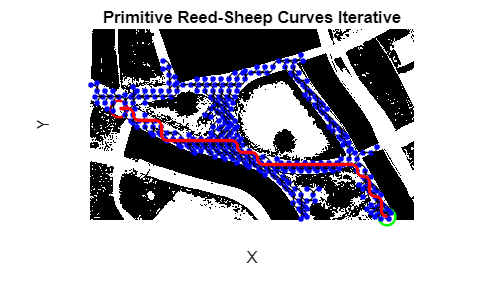

optimal_path = reconstructPath(parent, current, samplePoints);

## FUNCTIONS

function new_points = calculate_points(current_point, current_angle, iteration)
    % Global variables
    global length_step radius_curve num_iterations points counter occupancy_matrix samplePoints connections curve_points
    
    % Initialization of the new points
    new_points = [];

    % Condition of termination of recursion
    if iteration > num_iterations
        return;
    end

    % Calculation of the next point forward
    punto_avanti = round(current_point + length_step * [cos(current_angle), sin(current_angle)]);
    punto_finale_avanti = punto_avanti;

    % Center of the circumference for the right turn
    centro_destra = current_point + radius_curve * [cos(current_angle - pi/2), sin(current_angle - pi/2)];

    % Center of circumference for left turn
    centro_sinistra = current_point + radius_curve * [cos(current_angle + pi/2), sin(current_angle + pi/2)];

    % Angles to generate quarter circles
    theta_destra = linspace(current_angle + pi/2, current_angle, 100);
    theta_sinistra = linspace(current_angle - pi/2, current_angle, 100);

    x_destra = centro_destra(1) + radius_curve * cos(theta_destra);
    y_destra = centro_destra(2) + radius_curve * sin(theta_destra);
    punto_finale_destra = round([x_destra(end), y_destra(end)]);

    x_sinistra = centro_sinistra(1) + radius_curve * cos(theta_sinistra);
    y_sinistra = centro_sinistra(2) + radius_curve * sin(theta_sinistra);
    punto_finale_sinistra = round([x_sinistra(end), y_sinistra(end)]);

    % Adding points and curves to the plot only if they do not match previous points
    hold on;

    if is_within_bounds(punto_finale_avanti) && ~is_point_visited(punto_finale_avanti)
        x_points = round(linspace(current_point(1), punto_finale_avanti(1), 300));
        y_points = round(linspace(current_point(2), punto_finale_avanti(2), 300));
        if ~is_collision_avanti(current_point, punto_finale_avanti)
            counter = counter + 1;
            points(counter, :) = punto_finale_avanti;
            samplePoints = [samplePoints; punto_finale_avanti];
            occupancy_matrix(x_points, y_points) = 1;
            plot([current_point(1), punto_finale_avanti(1)], [current_point(2), punto_finale_avanti(2)], 'k-', 'LineWidth', 0.5);
            plot(punto_finale_avanti(1), punto_finale_avanti(2), 'b.', 'MarkerSize', 10);
            new_points = [new_points; punto_finale_avanti, current_angle, iteration + 1];
            connections = [connections; current_point, punto_finale_avanti];
        end
    end

    if is_within_bounds(punto_finale_destra) && ~is_point_visited(punto_finale_destra)
        if ~is_collision_curve(x_destra, y_destra)
            counter = counter + 1;
            points(counter, :) = punto_finale_destra;
            samplePoints = [samplePoints; punto_finale_destra];
            occupancy_matrix(round(x_destra), round(y_destra)) = 1;
            plot(x_destra, y_destra, 'k-', 'LineWidth', 0.5);
            plot(x_destra(end), y_destra(end), 'b.', 'MarkerSize', 10);
            new_points = [new_points; punto_finale_destra, current_angle - pi/2, iteration + 1];
            connections = [connections; current_point, punto_finale_destra];
        
            % Save the right corner points
            curve_points(end+1).start_node = current_point;
            curve_points(end).end_node = punto_finale_destra;
            curve_points(end).points = [x_destra', y_destra'];
        end
    end

    if is_within_bounds(punto_finale_sinistra) && ~is_point_visited(punto_finale_sinistra)
        if ~is_collision_curve(x_sinistra, y_sinistra) 
            counter = counter + 1;
            points(counter, :) = punto_finale_sinistra;
            samplePoints = [samplePoints; punto_finale_sinistra];
            occupancy_matrix(round(x_sinistra), round(y_sinistra)) = 1;
            plot(x_sinistra, y_sinistra, 'k', 'LineWidth', 0.5);
            plot(x_sinistra(end), y_sinistra(end), 'b.', 'MarkerSize', 10);
            new_points = [new_points; punto_finale_sinistra, current_angle + pi/2, iteration + 1];
            connections = [connections; current_point, punto_finale_sinistra];
            
            % Save the left corner points
            curve_points(end+1).start_node = current_point;
            curve_points(end).end_node = punto_finale_sinistra;
            curve_points(end).points = [x_sinistra', y_sinistra'];
        end
    end
end

Function to check if a point has already been visited

function visited = is_point_visited(punto)
    global occupancy_matrix
    visited = false;
    if occupancy_matrix(punto(1), punto(2)) == 1
        visited = true;
    end
end

Function to check if a point is within the limits of the matrix

function within_bounds = is_within_bounds(punto)
    global occupancy_matrix
    within_bounds = punto(1) > 0 && punto(2) > 0 && punto(1) <= size(occupancy_matrix, 1) && punto(2) <= size(occupancy_matrix, 2);
end

Function to check if a point is within the limits of the matrix

function collision_avanti = is_collision_avanti(current_point, punto_finale_avanti)
    global map

    collision_avanti = false;
    % Calculate points equidistant between start and end
    x_points = round(linspace(current_point(1), punto_finale_avanti(1), 300));
    y_points = round(linspace(current_point(2), punto_finale_avanti(2), 300));
    for i = 2:(length(x_points)-1)
        if map(x_points(i), y_points(i)) == 0
            collision_avanti = true;
            break
        end
    end
end

Function to check if a point is within the limits of the matrix

function collision_curve = is_collision_curve(x, y)
    global map

    collision_curve = false;
    for i = 2:(length(x)-1)
        if map(round(x(i)), round(y(i))) == 0
            collision_curve = true;
            break
        end
    end
end

Function that based on how the nodes are connected creates the adjacent matrix

function adjacency_matrix = create_adjacency_matrix(nodi, connections)
    num_nodi = size(nodi, 1);
    adjacency_matrix = zeros(num_nodi);

    for i = 1:size(connections, 1)
        punto1 = connections(i, 1:2);
        punto2 = connections(i, 3:4);
        
        idx1 = find(ismember(nodi, punto1, 'rows'));
        idx2 = find(ismember(nodi, punto2, 'rows'));
        
        if ~isempty(idx1) && ~isempty(idx2)
            adjacency_matrix(idx1, idx2) = 1;
            adjacency_matrix(idx2, idx1) = 1;
        end
    end
end


Function to find the path using BFS

function [parent, current] = findPathBFS(adjacency_matrix, samplePoints, Qs, Qg)
    nodes = samplePoints;
    num_samples = size(nodes, 1);

    % Find indices of start and goal nodes in nodes array
    [~, Qstart_index] = min(pdist2(nodes, Qs));
    [~, Qgoal_index] = min(pdist2(nodes, Qg));

    % BFS initialization
    queue = Qstart_index;              % Start with the index of the start node
    parent = zeros(1, num_samples);
    visited = false(1, num_samples);
    visited(Qstart_index) = true;      % Mark start node as visited

    % BFS search
    while ~isempty(queue)
        current = queue(1);
        queue(1) = [];
        
        if current == Qgoal_index
            % Reconstruct the path from goal to start
            % Interpolate the path
            % Both are done in the main
            return;
        end
        
        % Explore neighbors (nodes connected to current)
        neighbors = find(adjacency_matrix(current,:) == 1);
        for i = 1:length(neighbors)
            if ~visited(neighbors(i))
                visited(neighbors(i)) = true;
                parent(neighbors(i)) = current;
                queue(end+1) = neighbors(i);
            end
        end
    end
end

Reconstructs the previously obtained path plotting it

function path = reconstructPath(parent, goal, nodes)
    path = [];
    current = goal;
    while current ~= 0
        path = [current, path];
        current = parent(current);
    end
    plotPath(path, nodes, 'r');
end

function plotPath(path, nodes, color)
    global curve_points;
    for i = 1:length(path)-1
        start_node = path(i);
        end_node = path(i+1);
        
        % Check if there is a curve between these nodes
        curve_index = findCurveIndex(nodes(start_node,:), nodes(end_node,:));
        if ~isempty(curve_index)
            curve = curve_points(curve_index).points;
            plot(curve(:,1), curve(:,2), 'Color', color, 'LineWidth', 2);
        else
            plot([nodes(start_node,1), nodes(end_node,1)], [nodes(start_node,2), nodes(end_node,2)], 'Color', color, 'LineWidth', 2);
        end
    end
end

function index = findCurveIndex(start_node, end_node)
    global curve_points;
    index = [];
    for i = 1:length(curve_points)
        curve = curve_points(i);
        if (isequal(curve.start_node, start_node) && isequal(curve.end_node, end_node)) || ...
           (isequal(curve.start_node, end_node) && isequal(curve.end_node, start_node))
            index = i;
            break;
        end
    end
end